# **Simple Impedance Control Example**

- **Define simulation time**

- **Define original system dynamics **

- **Define desired system dymamics **

- **Define control law (input control force, u)**

- **Simulate impedance control & compare with desired system**

clear, clc

% Define time 
dt = 0.1;
t = (0:dt:10)';

## Original system

- Assume no gravity

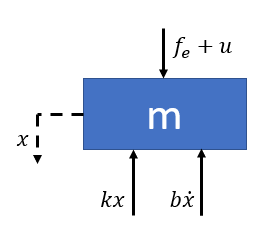 

EOM: $m\ddot{x} +b\dot{x} +\mathit{kx}=f_e +u$

Differential Equation format: $\dot{X} =\mathit{AX}+\mathit{BU}$

- From the EOM, we know: $\dot{x} =\frac{\textrm{d}}{\textrm{d}t}x$ and $\ddot{x} =\frac{-1}{m}\left(b\dot{x} +\mathit{kx}+f_e +u\right)$

- State Space format:

                    
$$\left\lbrack \begin{array}{c}
\dot{x} \\
\ddot{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{k}{m} & -\frac{b}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\dot{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f_e +u
\end{array}\right\rbrack$$


m = 1;  % kg
b = 1;  % N*s/m
k = 20; % N/m

% Control input force
u = @(t)zeros(size(t));

% External force/disturbance, fe
fe = @(t) 10*(t < 0); 

% EOM
sys = @(t, x)[0 1; -k/m -b/m]*x + [0; 1/m]* (u(t) + fe(t));

% Define I.C.
X0 = [1; 0];

% Differential Equation
[time,y] = ode45(sys,[0 t(end)],X0);


## Desired System

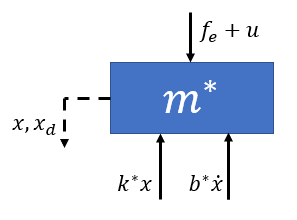

- Define desired mass, damping, and spring term, $m^* ,b^* ,\mathrm{and}\;k^*$.

- Define desired position trajectory, $x_d =0$ 

- EOM: $m^* \ddot{x} +b^* \left(\dot{x} -\dot{x_d } \right)+k^* \left(x-x_d \right)=fe+u$

ms = 1;
bs = 4;
ks = 10;

% control input force
u = @(t)zeros(size(t));

% EOM
sys_desired = @(t, xs)[0 1; -ks/ms -bs/ms]*xs + [0; 1/ms]* (u(t) + fe(t));

% Define I.C.
X0 = [1; 0];

% Differential Equation
[time_des,y_desired] = ode45(sys_desired,[0 t(end)],X0);


## Define control law, *u_fcn*

- Design *u_fcn* s.t. $u_{_\;\mathrm{fcn}\;} =\mathrm{func}\left(f_e ,x,x_d ,\dot{x} ,\dot{x_d } \right)$

- Solve desired system EOM for acceleration: $\ddot{x} =\frac{1}{m^* }\left(-b^* \left(\dot{x} -\dot{x_d } \right)-k^* \left(x-x_d \right)+f_e \right)$

- Substitude $\ddot{x} \;$into original system EOM and solve for *u_fcn*

             
$$u_\mathrm{fcn}=\frac{m}{m^* }\left(-b^* \left(\dot{x} -\dot{x_d } \right)-k^* \left(x-x_d \right)+f_e \right)+b\dot{x} +\mathit{kx}-f_e$$


- In differential equation format: $u_\mathrm{fcn}=\frac{m}{m^* }\left(-\left\lbrack k^* ,b^* \right\rbrack *\left\lbrack \begin{array}{c}
x\\
\dot{x} 
\end{array}\right\rbrack +f_e \right)+\left\lbrack k,b\right\rbrack *\left\lbrack \begin{array}{c}
x\\
\dot{x} 
\end{array}\right\rbrack -f_e$

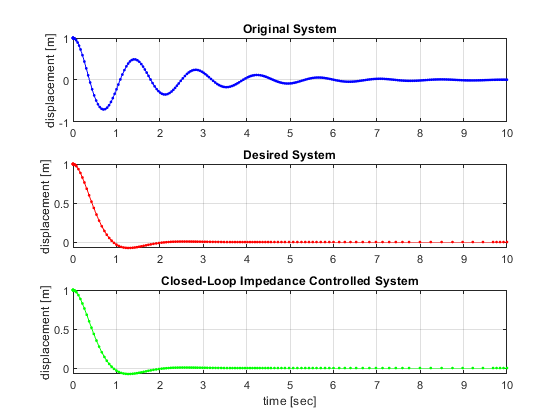

% Input control force
u_fcn = @(t, x, fe)(m/ms)*(-[ks, bs]*x + fe) + [k, b]*x - fe;   

% Simulate impedance controller
imp_sys = @(t, x)[0 1; -k/m -b/m]*x + [0; 1/m]* (u_fcn(t, x, fe(t)) + fe(t));
[time_imp,y_imp] = ode45(imp_sys,[0 t(end)],X0);

% Plot results
figure, 
subplot(311), plot(time(:,1), y(:,1), 'b.-'), grid on
title('Original System'), ylabel('displacement [m]')
subplot(312), plot(time_des(:,1), y_desired(:,1), 'r.-'), grid on
title('Desired System'), ylabel('displacement [m]')
subplot(313), plot(time_imp(:,1), y_imp(:,1), 'g.-'), grid on
title('Closed-Loop Impedance Controlled System'), xlabel('time [sec]'), ylabel('displacement [m]')